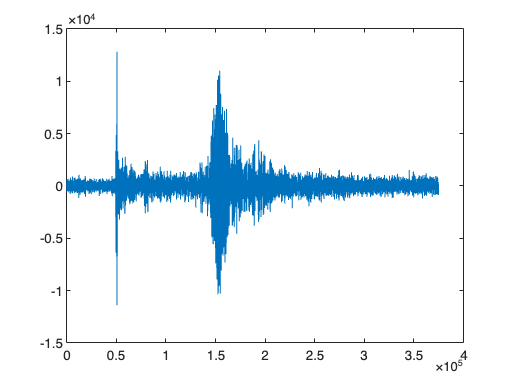

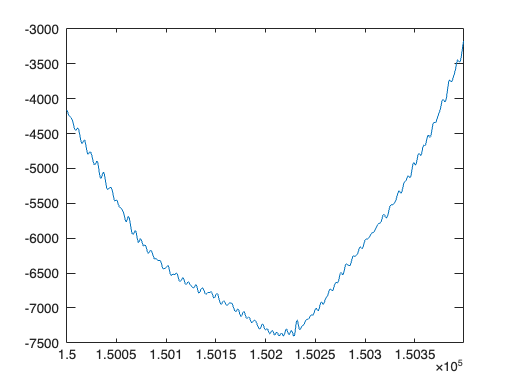

ans =     0.5000
    1.5000
    1.5000
         0
   -0.5000


ans =     1.5000
    1.5000
         0
   -0.5000


# Exercise 4 - Basic Data Analysis

### a)


fn = "data.h5";
info = h5info(fn);
group_name = info.Groups.Name;
ds_name = info . Groups . Datasets .Name;
data = h5read(fn , [group_name '/' ds_name]);

plot(data)

### b)

n_start = 1.5*10^5;
n_end = n_start + 400;
plot(data)
xlim([n_start, n_end-1])

### c)

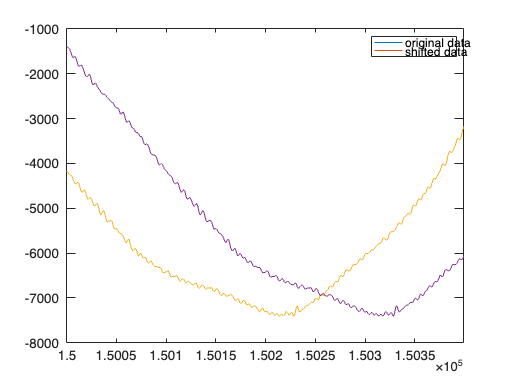

pad = zeros([100 1]);
shifted_data = [pad; data];

hold("on");
plot(data)
plot(shifted_data)
xlim([n_start, n_end-1])
hold("off");
legend("original data", "shifted data");